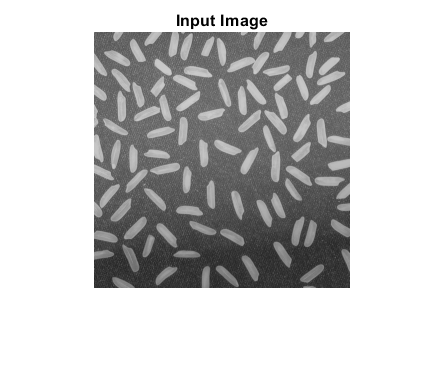

clc
clear all
close all
warning off
x=im2double(imread('rice.png'));
figure;
imshow(x);
title('Input Image');

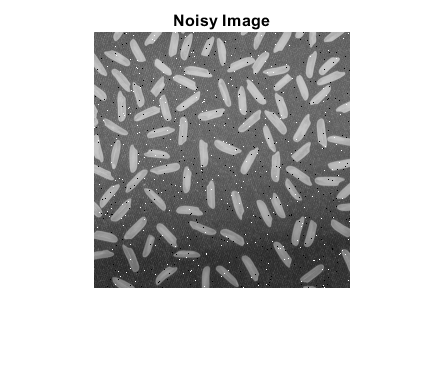

es=imnoise(x,'salt & pepper', 0.01);
figure;
imshow(es);
title('Noisy Image');

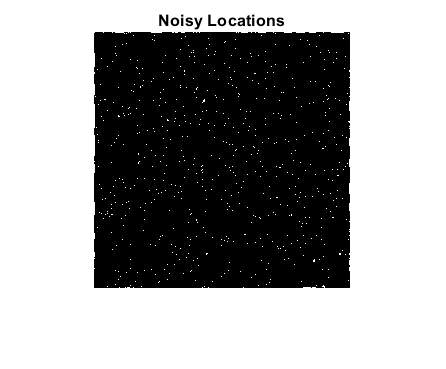

mask=[1 1 1;1 0 1;1 1 1]/8;
filt=imfilter(es,mask);
figure;
diff=abs(es-filt)>0.2;
imshow(diff);
title('Noisy Locations');

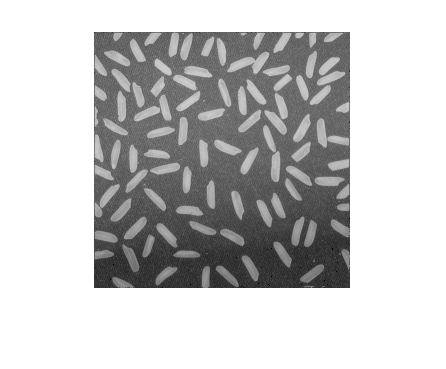

figure;
recovered_image=diff.*filt+(1-diff).*es;
imshow(recovered_image);